results = cell(1, 10);  % Store output from each run
times = cell(1, 10);    % Store time vector

for i = 1:10
    disp(['Running iteration ', num2str(i)]);

    % Run model
    sim('flann_architecture', 'StopTime', '0.0001668');

    % Extract timeseries data
    y = squeeze(ans.simout.Data);
    t = ans.simout.Time;

    % Save for this iteration
    results{i} = y;
    times{i} = t;

    % Display quick look
    disp(['First 5 output values of run ', num2str(i), ':']);
    disp(y(1:5));
end

Running iteration 1


First 5 output values of run 1:


    0.0270
    0.0018
    0.3723
    0.0589
    0.2046



Running iteration 2


First 5 output values of run 2:


    0.4626
    0.1607
    0.1920
    0.1158
    0.0631



Running iteration 3


First 5 output values of run 3:


    0.0177
    0.9391
    0.0081
    0.1996
    0.0891



Running iteration 4


First 5 output values of run 4:


    0.7577
    0.3140
    0.1047
    0.0059
    0.0064



Running iteration 5


First 5 output values of run 5:


    0.0004
    0.1791
    0.0126
    0.0016
    0.0023



Running iteration 6


First 5 output values of run 6:


    0.0126
    0.4691
    0.2359
    0.1272
    0.0109



Running iteration 7


First 5 output values of run 7:


    0.7381
    0.1659
    0.1417
    0.0424
    0.0041



Running iteration 8


First 5 output values of run 8:


    0.5326
    0.1369
    0.0306
    0.0427
    0.0123



Running iteration 9


First 5 output values of run 9:


    0.7694
    0.3188
    0.0600
    0.3681
    0.1209



Running iteration 10


First 5 output values of run 10:


    0.0130
    0.5443
    0.3000
    0.1175
    0.0182



%% Convert cell array to matrix
% Convert the 1x10 cell (each cell: 6005x1) to a 10x6005 matrix
% Preallocate
err_mat = zeros(10, 6005);

% Fill each row from the cell
for i = 1:10
    err_mat(i, :) = results{i}';  % Transpose column vector to row
end

%% Smoothing
disp('Please Wait! Smoothing Operation is Going On...');

Please Wait! Smoothing Operation is Going On...


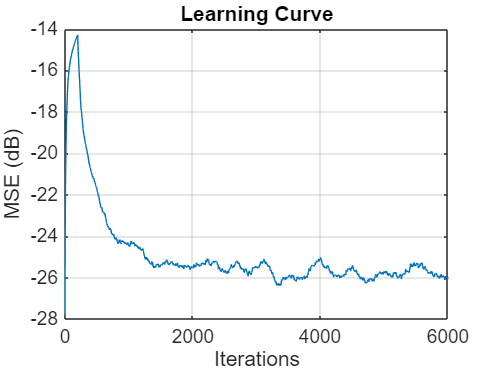

length_of_smoothing_filter = 200;
smoothing_filter_coeff = (1 / length_of_smoothing_filter) * ones(1, length_of_smoothing_filter);

err_smooth = zeros(size(err_mat));
for i = 1:10
    err_smooth(i,:) = filter(smoothing_filter_coeff, 1, err_mat(i,:));
end
%% Plot Learning Curve
figure;
plot(10 * log10(mean(err_smooth))); 
xlabel('Iterations');
ylabel('MSE (dB)');
title('Learning Curve');
grid on;


%% Average MSE over last 1000 iterations
fln_mse = 10 * log10(mean(mean(err_mat(:, end-999:end))));
fprintf('Average MSE Value over the last 1000 iterations is %f dB\n', fln_mse);

Average MSE Value over the last 1000 iterations is -25.744160 dB
